# Lab 1

## Kurt Delegard

## PHYS 434 AB

clear;
clc;

### 1. Plotting the normal distribution, probabilities, and 'sigma'

Here we plot the standard normal distribution for reference. A random data set consisting of 100,000 data points with an approximately normal distribution has also been shown.

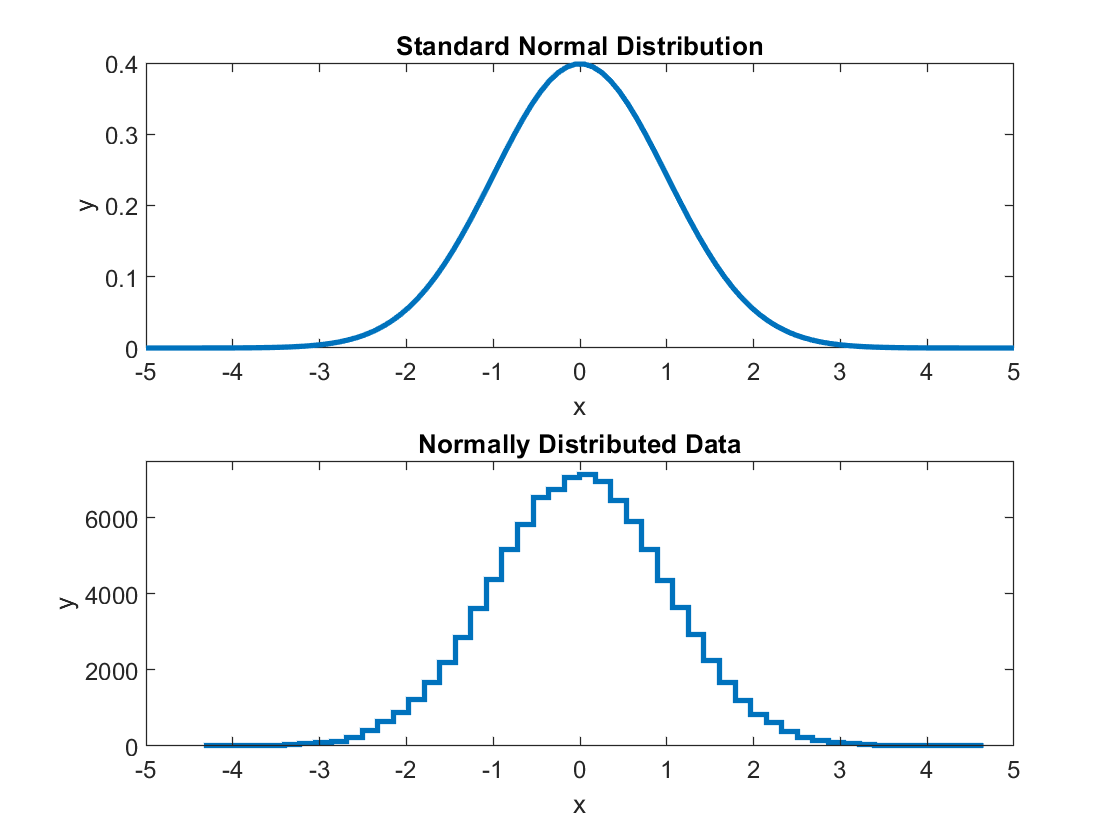

xs = linspace(-5,5,100);
ys = normpdf(xs, 0, 1);

subplot(2, 1, 1)
plot(xs, ys, 'linewidth', 2)
title("Standard Normal Distribution")
xlim([-5 5]);
xlabel("x");
ylabel("y");

subplot(2, 1, 2)
d = random('Normal', 0, 1, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',2)
xlim([-5 5]);
ylim([0 7500])
title("Normally Distributed Data");
xlabel("x");
ylabel("y");

Calculate the integrals (probabilities) for multiple values of sigma:

sigma_neg_10 = -10;
normal_integral_neg_10 = erfc(sigma_neg_10)

normal_integral_neg_10 = 2

sigma_0 = 0;
normal_integral_0 = erfc(sigma_0)

normal_integral_0 = 1

sigma_1 = 1;
normal_integral_1 = erfc(sigma_1)

normal_integral_1 = 0.1573

sigma_10 = 10;
normal_integral_10 = erfc(sigma_10)

normal_integral_10 = 2.0885e-45

For the given probabilities, calculate the associated sigma:

prob_1 = normal_integral_1;
sigma1 = norminv(prob_1)

sigma1 = -1.0056

The sigma value 1 is associated with the probability 0.1573, as shown above. The minus sign is due to the fact that we are measuring the probabilities of values to the left of the mean, assuming sigma = 0 at the mean.

We can account for this convention in our calculations by recording the absolute value of sigma.

prob_Inf = 1;
sigmaInf = norminv(prob_Inf)

sigmaInf = Inf

The sigma value for a probability of 100% is infinity. This is to be expected; the normal distribution approaches zero as values of x go to infinity. Therefore, an integral which sums the entire area under the curve will range from negative infinity to positive infinity.

### 2. Non-Gaussian distributions

Here we plot the lognormal distribution. As before, a random data set consisting of 100,000 data points with an approximately normal distribution has also been shown.

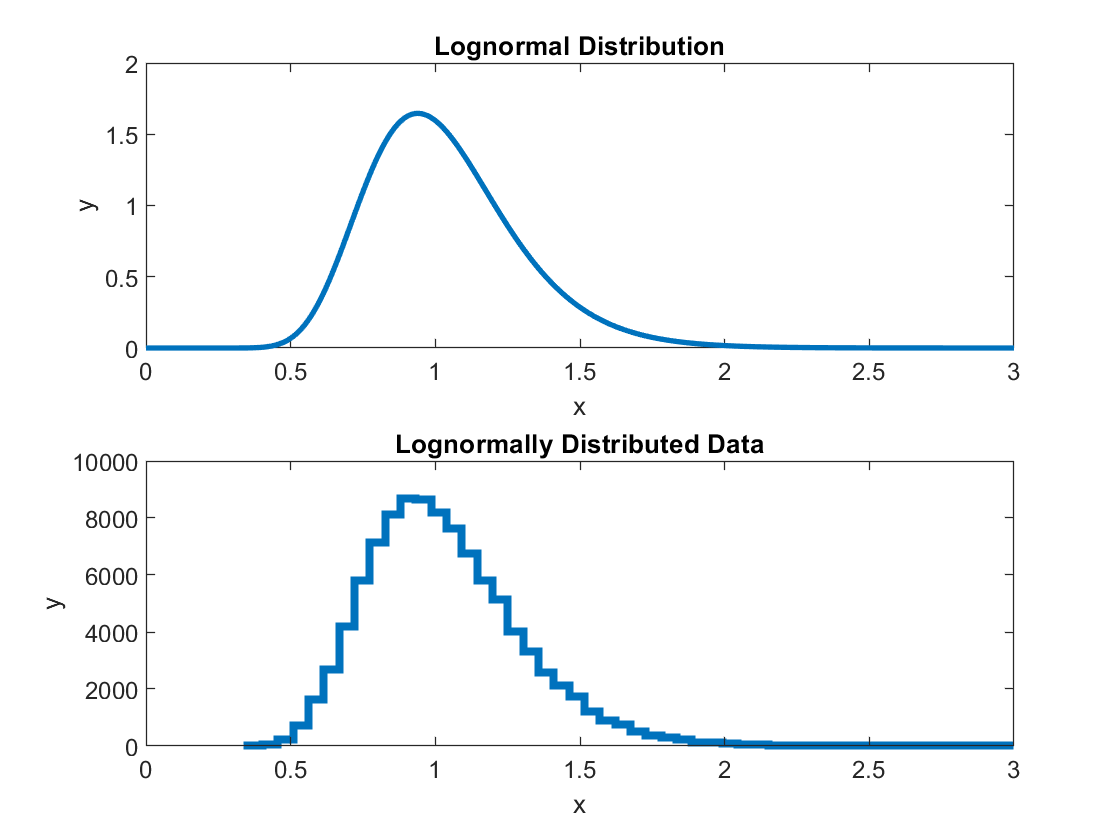

clear;
clf;
xs = linspace(0, 10, 100000)';
%ys = pdf('lognormal', xs, )

subplot(2, 1, 1);
x = linspace(0,3,100000);
pd = makedist("Lognormal",0, 0.25);
plot(x,pdf(pd,x),"LineWidth",2);
title('Lognormal Distribution');
xlabel('x');
ylabel('y');
xlim([0 3]);

subplot(2, 1, 2);
d = random('Lognormal', 0, 0.25, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
title('Lognormally Distributed Data');
xlabel('x');
ylabel('y');
xlim([0 3]);

### 3. Hypothetical measurements - background vs. signal

Let us assume that when a measurement yields a value of 2 or greater, it is considered to be a signal, while values lower than 2 are considered backround noise. This value will be referred to as the signal threshold.

**Statistical question:** What is the probability that the background will yield a measured value of 2.0 or more?

    To solve this question, all we have to do is integrate the probability distribution function from 2.0 to infinity. This is equivalent to reading the value of the cumulative distribution function at the value x = 2.0.


$${\displaystyle \int_2^{\infty} \!{\frac {1}{x\sigma {\sqrt {2\pi }}}}\ \exp \left(-{\frac {\left(\ln x-\mu \right)^{2}}{2\sigma ^{2}}}\right)dx}$$


*Integrating the lognormal probability distribution function from 2 to *∞.

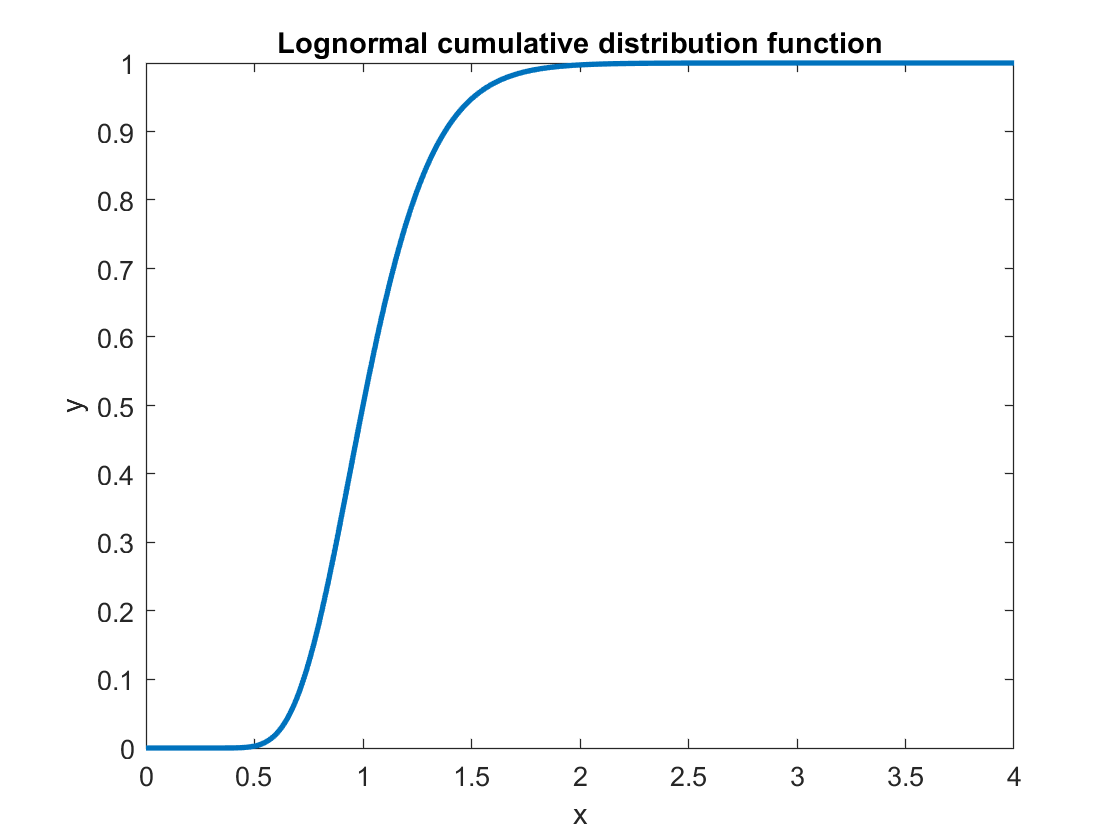

signal = 2;
clf;
plot(xs, cdf('Lognormal', xs, 0, 0.25), 'linewidth', 2)
xlim([0,4])
xlabel('x');
ylabel('y');
title('Lognormal cumulative distribution function');

The value of the cumulative distribution function at x = 2.0 represents the integral of the function from -∞ to 2. This is does not represent the probability that will answer our statistical question; however, we can solve this problem by subtracting the value we get from 1, since the maximum value of the cdf is 1.0.

cdf_2 = cdf('Lognormal', 2, 0, 0.25)

cdf_2 = 0.9972

probability = 1-cdf_2

probability = 0.0028

Therefore, 0.28% is the probability that the background produced a data point that is as signal-like or more than an actual signal, given that the threshold for measuring a signal is 2.0.

sigma_background = abs(norminv(probability))

sigma_background = 2.7726

A measurement of the background at this threshold would be 2.77 standard deviations away from the mean of the distribution. 

By varying our signal threshold, we can observe how likely the lognormally distributed background data would appear to provide a signal-like measurement. Here we plot values of sigma vs. the signal threshold on a linear scale.

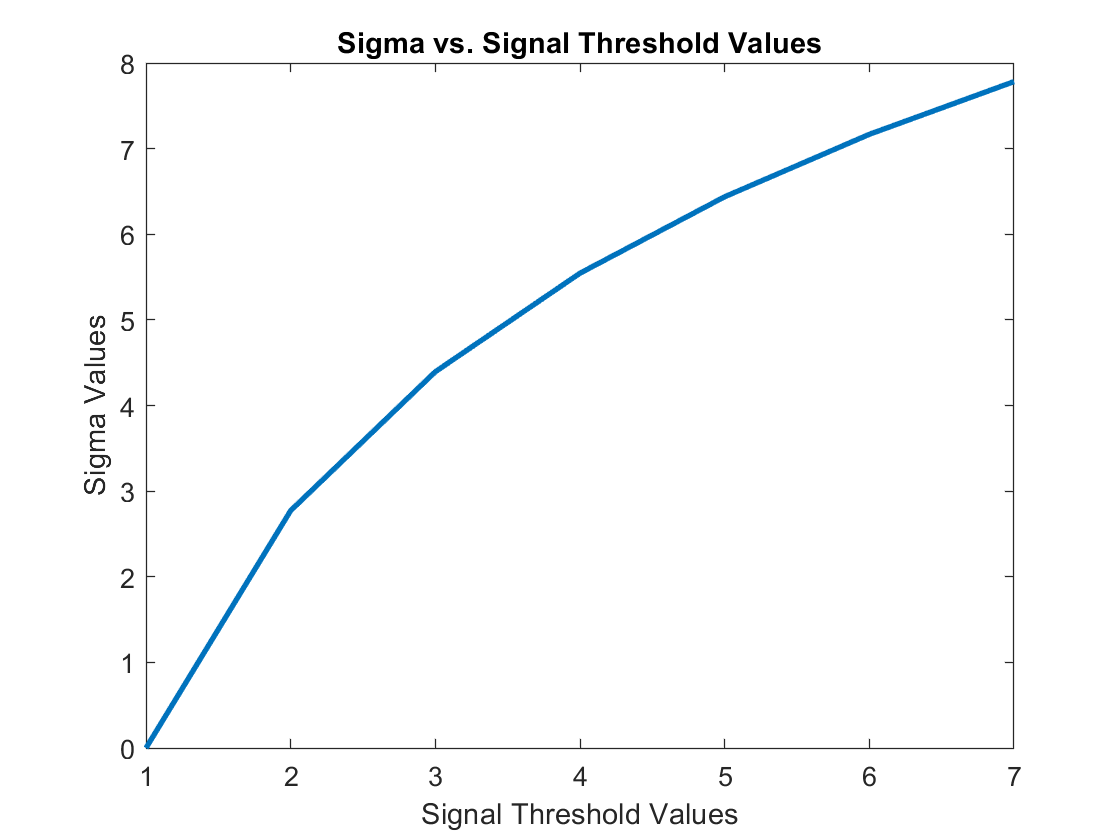

signal_thresholds = [1:10000];
sigma_values = [1:10000];

for nn = 1:10000
    cdf_at_threshold = cdf('Lognormal', nn, 0, 0.25);
    probability_at_threshold = 1-cdf_at_threshold;
    sigma_at_threshold = norminv(probability_at_threshold);
    sigma_values(nn) = abs(sigma_at_threshold);
end

clf;
plot(signal_thresholds, sigma_values, 'linewidth', 2);
title('Sigma vs. Signal Threshold Values');
xlabel("Signal Threshold Values");
ylabel("Sigma Values");

Note that larger values of sigma correspond to smaller probabilities. This is because large values of sigma correspond to greater distances from the mean to the x-value in question.

This relationship seems to follow an inverse-logarithmic trend. We can observe this by plotting the x-axis on a logarithmic scale:

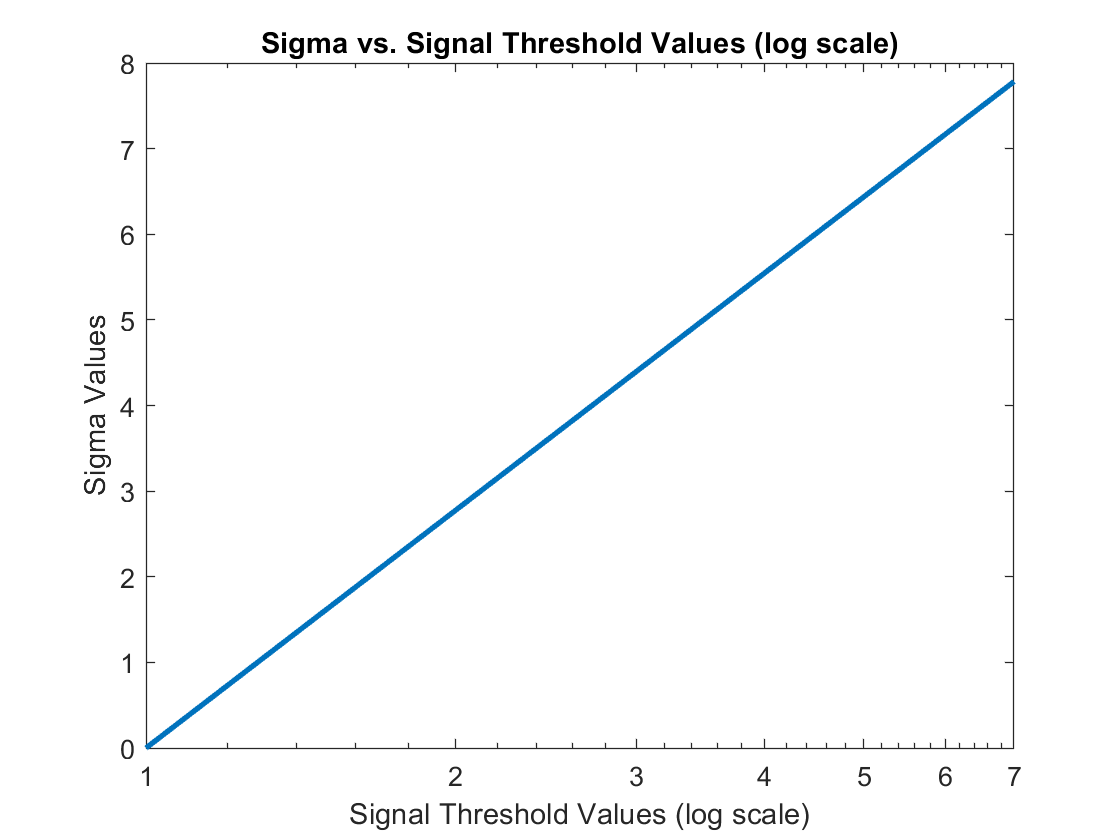

semilogx(signal_thresholds, sigma_values, 'linewidth', 2);
title('Sigma vs. Signal Threshold Values (log scale)')
xlabel("Signal Threshold Values (log scale)");
ylabel("Sigma Values");

This is to be expected - by taking the logarithm of a lognormal distribution, we get a Gaussian distribution, which has a linear relationship between distance from the mean (sigma) and the associated probability of the corresponding value.

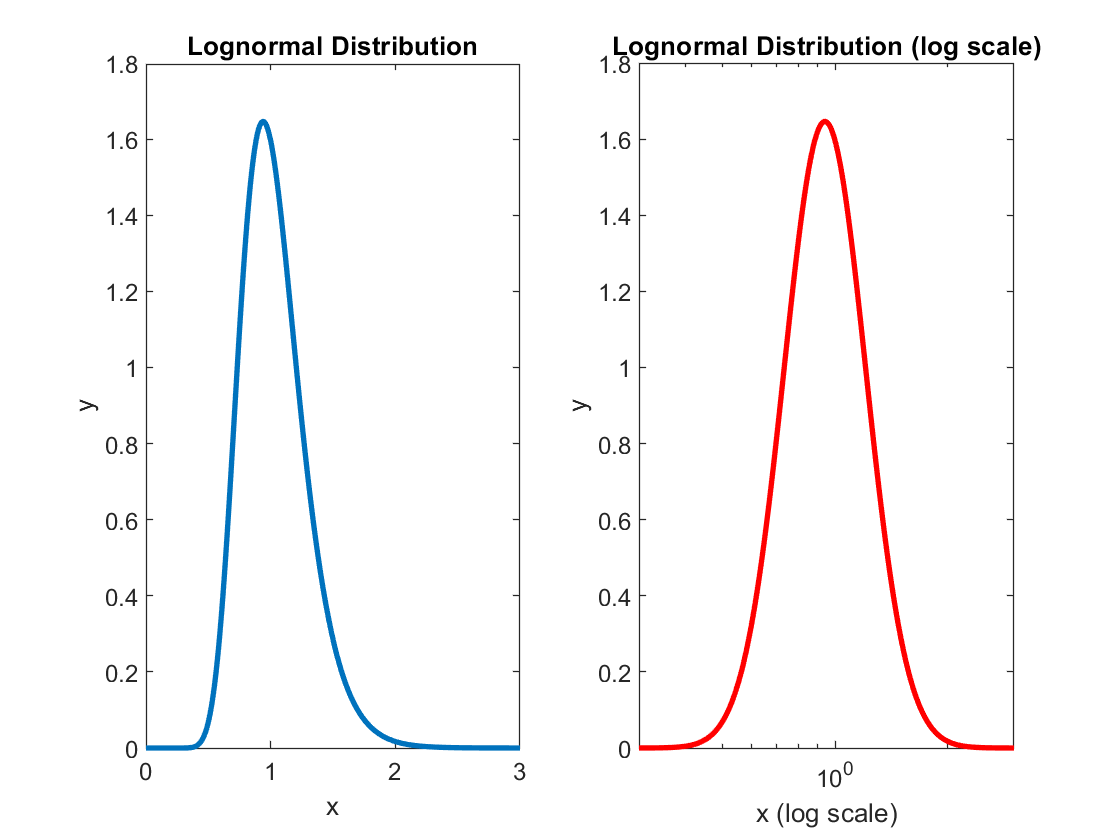

clf;
subplot(1, 2, 1);
x = linspace(0,3,100000);
pd = makedist("Lognormal",0, 0.25);
plot(x,pdf(pd,x),"LineWidth",2);
title('Lognormal Distribution');
xlabel('x');
ylabel('y');
xlim([0 3]);

subplot(1, 2, 2);
x = linspace(0,3,100000);
pd = makedist("Lognormal",0, 0.25);
semilogx(x,pdf(pd,x), 'r-', "LineWidth",2);
title('Lognormal Distribution (log scale)');
xlabel('x (log scale)');
ylabel('y');
xlim([0.3 3]);

## Non-Continuous distributions

### 1. Poisson Distribution

Here we will focus on the Poisson distribution, a discrete distribution function. The pdf takes one parameter, $\lambda$, which represents the average number of events in a fixed space or time interval. This could be the average number of decays in a sample of radioactive material in 1 hour, or the average number of atoms per meter in space. The pdf shows, over several measurement trials, how probable it is to measure any number of events within the measurement time or space period.

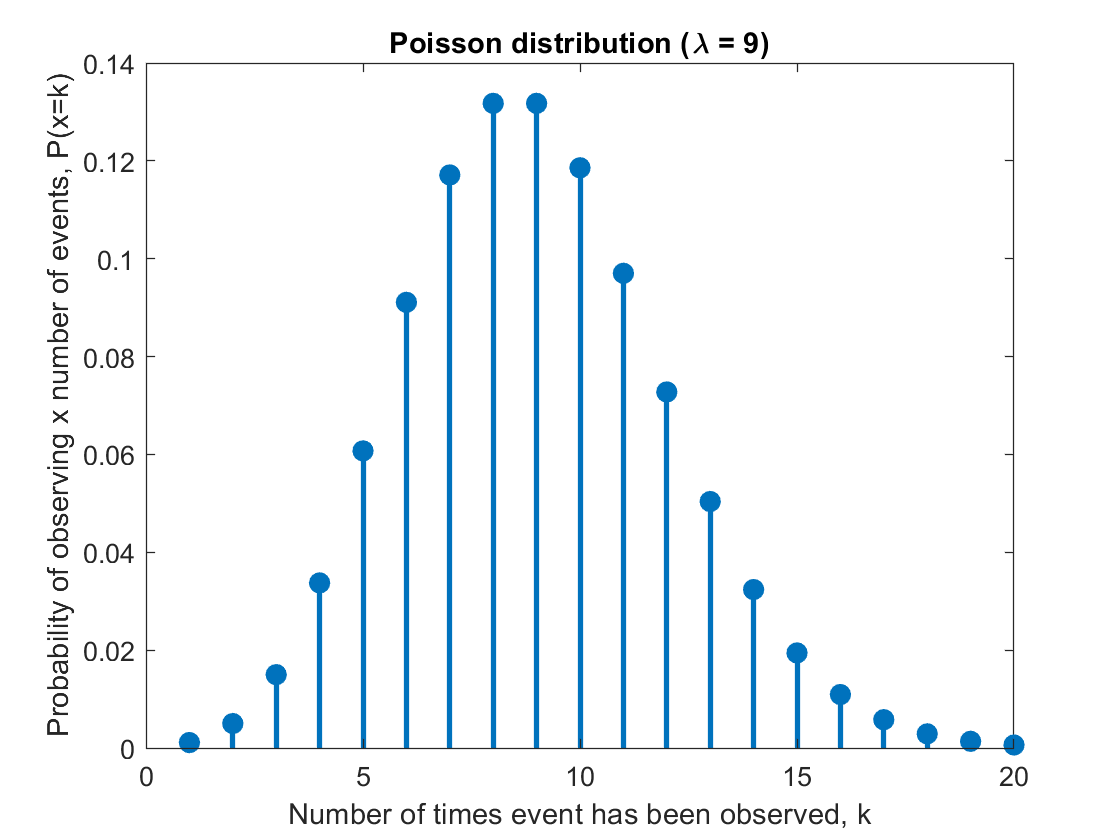

clear;
clc;
clf;

xs = 1:20;
ys_1 = poisspdf(xs, 9);
ys_2 = poisspdf(xs, 2);
ys_3 = poisspdf(xs, 16);

stem(xs, ys_1, 'filled', 'linewidth', 2)
title('Poisson distribution ({\lambda} = 9)')
xlabel("Number of times event has been observed, k")
ylabel('Probability of observing x number of events, P(x=k)')

Different values of $\lambda$ change the shape of the distribution - the peak of the pdf tends to be at the value $x=\lambda$:

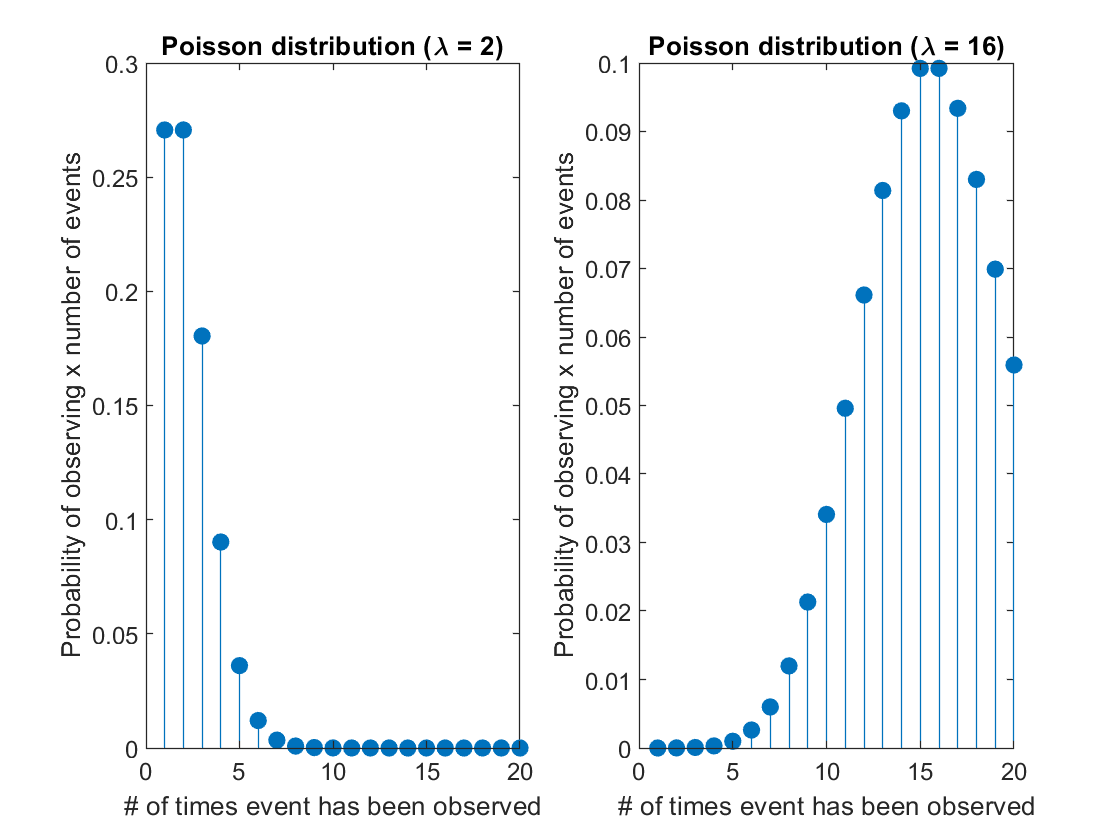

subplot(1, 2, 1);
stem(xs, ys_2, 'filled')
title('Poisson distribution ({\lambda} = 2)')
xlabel("# of times event has been observed")
ylabel('Probability of observing x number of events')

subplot(1, 2, 2);
stem(xs, ys_3, 'filled')
title('Poisson distribution ({\lambda} = 16)')
xlabel("# of times event has been observed")
ylabel('Probability of observing x number of events')

We will pose a hypothetical signal threshold, as before, to try to solve a similar statistical question. Using a Poisson distribution with $\lambda =9$, we will set a signal threshold of 15 events. 

**Statistical question: **What is the probability of observing 15 or more events?

The solution to this question is the same as before, only because this is a discrete distribution, we sum the probabilities corresponding to 15 events or more. This is equivalent to getting the value of the Poisson cumulative distribution function at x=15:

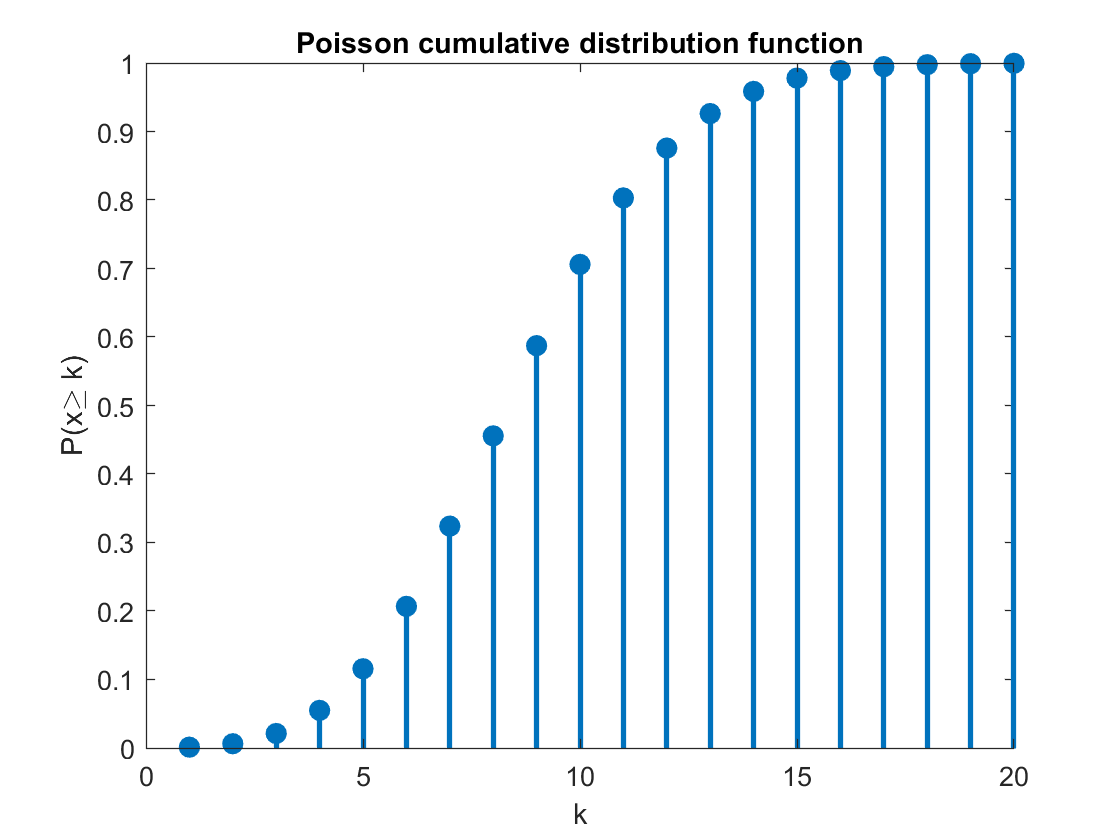

clf;
stem(xs, poisscdf(xs, 9), 'filled', 'linewidth', 2);
title('Poisson cumulative distribution function')
xlabel('k');
ylabel('P({x\geq k})')

Once again, the cumulative distribution function represents the discrete sum of values of k from 0 to the value in question. We want the discrete sum starting from the value in question and all values to the right. Again, we can solve this by subtracting the value of the cdf at 15 by 1:

pcdf = poisscdf(15, 9);
probability = 1 - pcdf

probability = 0.0220

The probability of observing 15 or more events is 2.20%.

sigma = abs(norminv(probability))

sigma = 2.0134

The sigma value associated with this probability is 2.013.

The probabilities and values of sigma for this distribution are discrete. This means that choosing an arbitrary value of sigma will likely yield zero probability - for example, there is a 0% chance of measuring 10.7 atoms, or 4.3 photons. Only the discrete values of sigma corresponding to discrete numbers of measurements are meaningful.

By varying the signal threshold for a specified value of $\lambda$, we can observe how the corresponding values of sigma change.

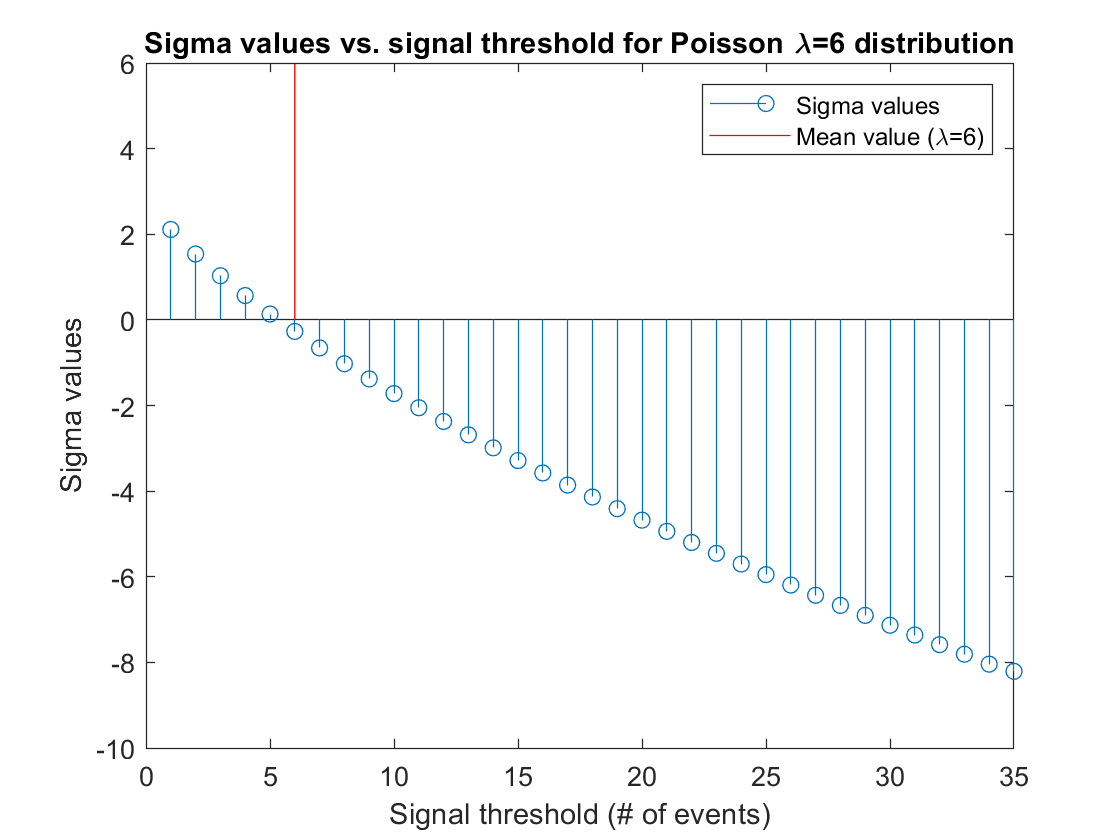

limit = 100;
signal_thresholds = [1:limit];
sigma_values = [1:limit];

lambda = 6;
for nn = 1:limit
    cdf_at_threshold = cdf('Poisson', nn, lambda);
    probability_at_threshold = 1-cdf_at_threshold;
    sigma_at_threshold = norminv(probability_at_threshold);
    sigma_values(nn) = sigma_at_threshold;
end

clf;
stem(signal_thresholds, sigma_values), hold on
plot([lambda lambda], [0 lambda], 'r-')
title('Sigma values vs. signal threshold for Poisson {\lambda}=6 distribution')
xlabel("Signal threshold (# of events)");
ylabel("Sigma values");
legend('Sigma values', 'Mean value ({\lambda}=6)')

The values of sigma are positive when the signal threshold is less than the mean, and are negative when the signal threshold is greater than the mean. This follows the same convention mentioned above, but only the absolute value of sigma is significant in this analysis.

The data seems to follow a decreasing exponential trend. This is true for Poisson distributions with small values of $\lambda$. By increasing $\lambda$, the data becomes more linear, as the distribution becomes approximately Gaussian at large values of $\lambda$:

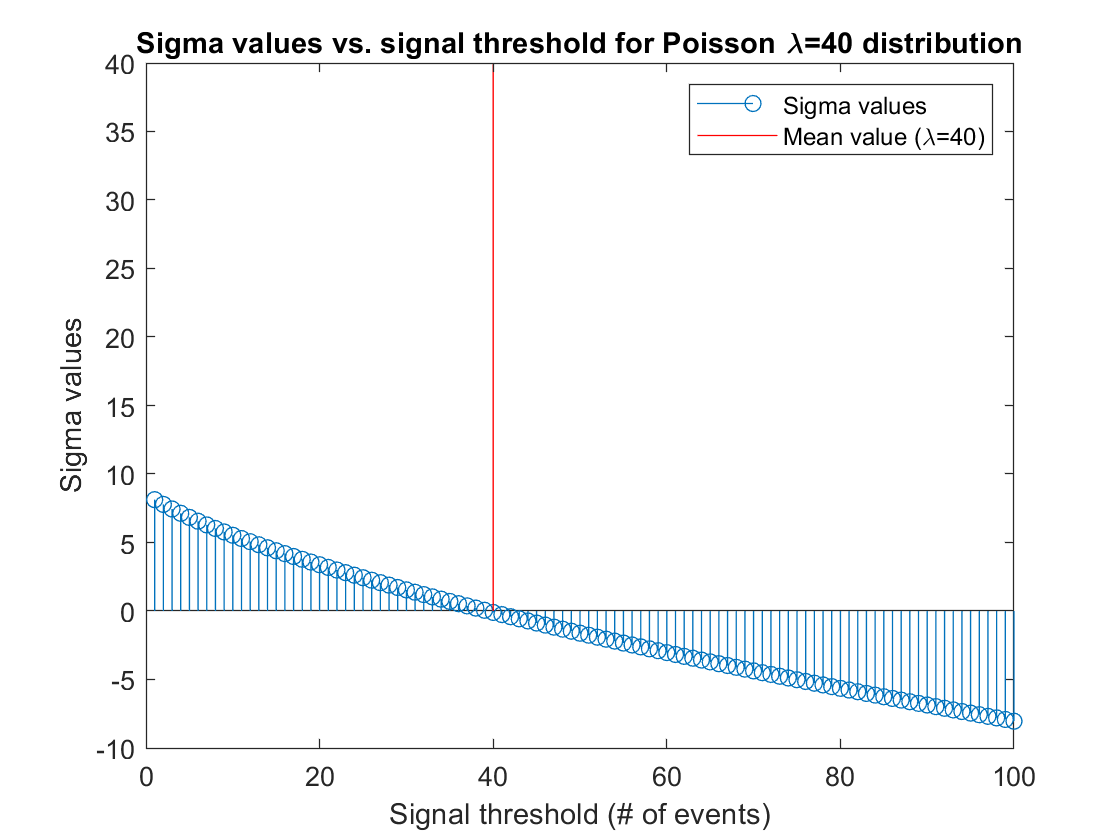

lambda = 40;
for nn = 1:limit
    cdf_at_threshold = cdf('Poisson', nn, lambda);
    probability_at_threshold = 1-cdf_at_threshold;
    sigma_at_threshold = norminv(probability_at_threshold);
    sigma_values(nn) = sigma_at_threshold;
end

clf;
stem(signal_thresholds, sigma_values), hold on
plot([lambda lambda], [0 lambda], 'r-')
title('Sigma values vs. signal threshold for Poisson {\lambda}=40 distribution')
xlabel("Signal threshold (# of events)");
ylabel("Sigma values");
legend('Sigma values', 'Mean value ({\lambda}=40)')

Final note: the mean of a Poisson distribution, $\lambda$, can be a non-integer value. While individual measurements must yield integer results, the average of several measurements is a quotient of two integers, which can be a non-integer value:

measurements = [4 5 8 13 9 2 18 5 7 10 3 16 10 9 12 5 19];
average = mean(measurements)

average = 9.1176

Therefore, while the mean value $\lambda$ can take on any continuous value, the individual measurement values, sigma values, and probabilities of measuring a certain number of events must be discrete.